addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01
t = 0 : t_step : t_end;

% generate figure noisy_optimising

n = 30;
taus = logspace(-5, -1, n);
chi2s = zeros([1, n]);

%{
band_width = 1000
band = [f_a-band_width/2, f_a+band_width/2];
    
%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

%% generate signal and noise
signal = calc_wave_with_frequency(t, f_sampling, f_axion);
signal = signal / sqrt( bandpower(signal, f_sampling, band) ); % get signal power in band = 1
noise = randn(size(t));
noise = noise / sqrt(bandpower(noise, f_sampling, band));

iwave_in = signal + noise;
iwave_input = prepare_iwave_input(iwave_in, f_a, band_width, f_sampling);

% front to chop off
start_secs = t(end)/4;
start = start_secs * f_sampling;
assert(start_secs < t(end)/3)

chop = @(arr) arr(start:end);
to_minimise = @(tau) sum(power(chop(f_axion - run_iwave(iwave_input, f_sampling, f_a, tau)), 2));

parfor i = 1 : n
    i
    chi2s(i) = to_minimise(taus(i));
end
%}

chi2s = [17545924954274.6	13892855968649.1	6114081154119.51	4569229136599.36	3734106706048.34	7442215487057.23	1208873895113.04	1021060961318.20	721555035894.041	649974478087.609	632495496641.955	813599263269.470	734144604048.956	642580270288.623	730880709678.183	694346374204.614	667865608580.009	644063267042.117	657093773074.481	673156472875.282	688005503181.797	700449651705.795	710333351466.545	717931908234.052	723655841324.349	727912723261.669	731053287127.770	733358719407.436	735045901807.619	736278257345.604];

adstyle(8, 8)
scatter(taus, chi2s)
set(gca,'Xscale','log','Yscale','log')
hold on
[m, i] = min(chi2s);
taus(i)

ans = 2.3950e-04

scatter(taus(i), m)
xlabel('\tau (s)')
ylabel('\chi^2')
y = ylim()

y = 1.0e+13 *

    0.0632    1.7546


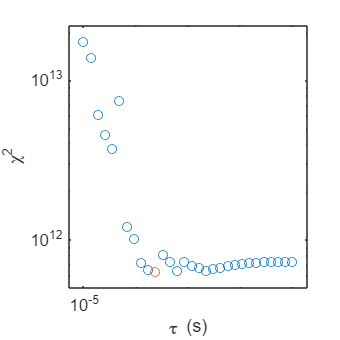

box on
axis padded

%ylim([y(1)*0.9, y(2)*1.1])

saveas(gca, 'figures/minimise.eps', 'epsc');

%17545924954274.6	13892855968649.1	6114081154119.51	4569229136599.36	3734106706048.34	7442215487057.23	1208873895113.04	1021060961318.20	721555035894.041	649974478087.609	632495496641.955	813599263269.470	734144604048.956	642580270288.623	730880709678.183	694346374204.614	667865608580.009	644063267042.117	657093773074.481	673156472875.282	688005503181.797	700449651705.795	710333351466.545	717931908234.052	723655841324.349	727912723261.669	731053287127.770	733358719407.436	735045901807.619	736278257345.604